clear;
clc;

% Lapso temporal
t = linspace(0, 3e4, 1e6);

% Constantes (SSO)
mu = 3.986004418e14;
J2 = 1.082635854e-3;
R = 6378.137e3;
a = 7211.54e3;
n = sqrt(mu ./ a.^3);
INC     = deg2rad(98.7);
omega   = deg2rad(30);
theta_0 = deg2rad(45);

% Condiciones iniciales
x0  = 0;
y0  = 0;
z0  = 0;
dx0 = 0;
dy0 = 0;
dz0 = 0;

% Identidades trigonométricas
nt = n.*t;
cnt = cos(nt);
snt = sin(nt);
c2nt = cos(2.*nt);
s2nt = sin(2.*nt);
c3nt = cos(3.*nt);
s3nt = sin(3.*nt);

si = sin(INC);
ci = cos(INC);
sw = sin(omega);
cw = cos(omega);
s2w = sin(2.*omega);
c2w = cos(2.*omega);
s3w = sin(3.*omega);
c3w = cos(3.*omega);

% Constantes de Kéchichian
k1 = dx0./n;
k2 = x0;
K  = dy0 + 2.*n.*x0 - 3./(4.*a).*n.*J2.*R.^2.*si.^2.*c2w;
Kp = y0 - 2.*dx0./n - 9./(8.*a).*J2.*R.^2.*si.^2.*s2w;

% Constantes de la memoria
sigma  = nt/2;
alpha1 =   omega +  theta_0;

beta1  =   sigma +   alpha1;
beta2  = 3*sigma + 2*alpha1;
beta3  =   sigma + 2*alpha1;
beta4  =   sigma - 2*alpha1;

kappa_i = 3*cos(2*INC) + 1;

u = alpha1 + 2*sigma;

% Solución analítica
xJ2B = (1 + 6.*sin(sigma).^2).*x0 + (sin(2*sigma)./n).*dx0 - (4./n).*sin(sigma).*dy0 ...
        - (R.^2.*J2)./(2.*a).*sin(sigma).^2 .* ( ...
            sin(INC).^2 .* (2.*cos(2.*beta1) + 7.*cos(2.*alpha1) - 9) ...
            + 6 ...
        );
xJ2K = k1.*snt + k2.*cnt - (3.*J2.*R.^2)./(2.*a).* ...
       ( - (si.^2.*s2w./6).*(-s2nt + 2..*snt) + ...
       (si.^2.*c2w./6).*(cnt - c2nt) + ...
       (1 - (3./2).*si.^2).*(1 - cnt) ) + ...
       (2.*K./n).*(1 - cnt);

xdotJ2B = 3.*n.*sin(2*sigma).*x0 ...
            + cos(2*sigma).*dx0 ...
            + 2.*sin(2*sigma).*dy0 ...
            + (n.*R.^2.*J2)./(4.*a) .* ( ...
                sin(2*sigma).*( ...
                    sin(INC)^2.*( ...
                        - 4*cos(2*beta1) ...
                        - 5*cos(2*alpha1) ...
                        + 9 ...
                    ) ...
                    - 6 ...
                ) ...
                - 4*sin(sigma).^2.*sin(2.*alpha1).*sin(INC).^2 ...
            );
xdotJ2K = n.*k1.*cnt - n.*k2.*snt + 2.*K.*snt - ...
          3.*J2.*R.^2./(2.*a).*(-si.^2.*s2w./3.*(-n.*c2nt + n.*cnt)  + ...
          si.^2.*c2w./6.*(-n.*snt + 2.*n.*s2nt) + ...
          (1 - 3./2.*si.^2).*n.*snt);

yJ2B = 6.*sin(n.*t).*x0 + y0 ...
        - (4./n).*sin(sigma).^2.*dx0 ...
        + (4./n).*sin(n.*t).*dy0 ...
        - (6.*n.*x0 + 3.*dy0 - (3.*n.*R.^2.*J2)./(4.*a) .* ( ...
            4 + 3.*sin(INC).^2 .* (cos(2.*alpha1) - 2) ...
        )).*t ...
        + (R.^2.*J2)./(8.*a) .* ( ...
            sin(4.*sigma).*sin(INC).^2 ...
            - 4.*sin(2.*sigma) .* ( ...
                sin(alpha1).*sin(INC).^2 .* (sin(u) - 10.*sin(alpha1)) ...
                + 4.*cos(INC).^2 + 2 ...
            ) ...
            - 16.*sin(sigma).^2.*sin(2.*alpha1).*sin(INC).^2 ...
        );
yJ2K = 2.*k1.*cnt - 2.*k2.*snt + ...
       3.*n./(2.*a).*J2.*R.^2 .* ...
       ( si.^2.*s2w./3 .* (c2nt./(4.*n) + 2.*cnt./n) + ...
       si.^2.*c2w .* ( 1./(3.*n).*snt + s2nt./(12.*n) ) + ...
       2 .* (1 - 3./2.*si.^2) .* (t - snt./n) ) ...
       - 3.*K.*t + 4.*K./n.*snt + Kp;

ydotJ2B = -12.*n.*sin(sigma).^2.*x0 ...
            - 2.*sin(2*sigma).*dx0 ...
            + (1 - 8.*sigma.^2).*dy0 ...
            + (n.*R.^2.*J2)./(4.*a).*sin(sigma) .* ( ...
                6*sin(sigma).*( ...
                    + 3*sin(INC)^2.*cos(2.*alpha1) ...
                    + kappa_i ...
                ) ...
                - sin(INC).^2.*( ...
                    2*sin(beta2) ...
                    + 5*sin(beta3) ...
                    - 5*sin(beta4) ...
                ) ...
            );
ydotJ2K = -2.*n.*k1.*snt - 2.*n.*k2.*cnt + ...
         (3.*n.*J2.*R.^2 ./ (2.*a)) .* ...
         ( -(si.^2 .* s2w ./ 3) .* (s2nt ./ 2 + 2.*snt)  + ...
         (si.^2 .* c2w) .* ( (1./3).*cnt + c2nt ./ 6 ) + ...
         2 .* (1 - (3./2).*si.^2) .* (1 - cnt) ) - ...
         3.*K + 4.*K.*cnt;

zJ2 = cos(2*sigma).*z0 + (sin(2*sigma)./n).*dz0 ...
        + (3.*R.^2.*J2)./(4.*a).*sin(2.*INC) .* ( ...
            2*sigma.*cos(u) - cos(alpha1).*sin(2*sigma) ...
        );
zdotJ2 = -n.*sin(2.*sigma).*z0 + cos(2.*sigma).*dz0 ...
        - (3.*n.*R.^2.*J2)./(4.*a).*sin(2.*INC) .* ( ...
            sin(2*sigma)*sin(alpha1) + 2.*sigma.*sin(u) ...
        );

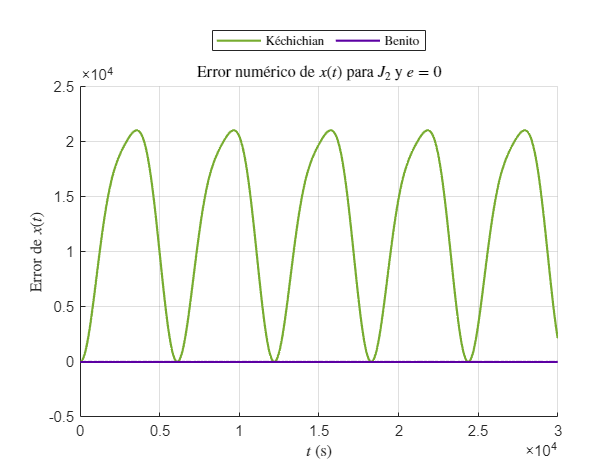

% Resolución
X0 = [x0, y0, z0, dx0, dy0, dz0];

opts = odeset('RelTol', 1e-12, 'AbsTol', 1e-5);
[~, dXdt] = ode113(@(ode, X) odeClohessyWiltshireJ2J3(ode, X, J2, 0, R, a, n, INC, omega, theta_0), t, X0, opts);
    
% Comparación
plotNumericErrors(   xJ2K',    xJ2B', dXdt(:, 1), t, 'K\''echichian', 'Benito', ...
          'Error num\''erico de $x(t)$ para $J_2$ y $e = 0$', '$t$ (s)',       'Error de $x(t)$', '#77AC30', '#5C00A3');

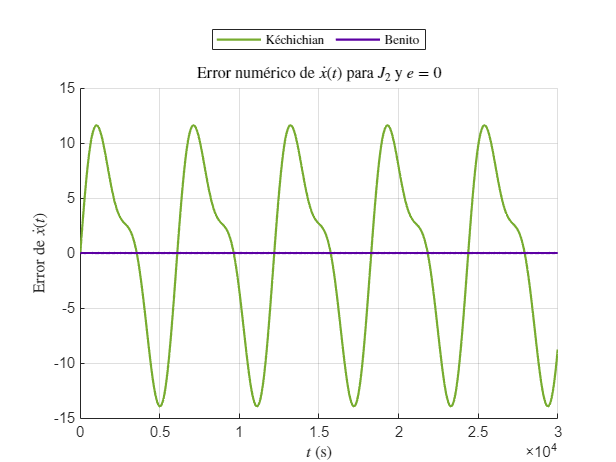

plotNumericErrors(xdotJ2K', xdotJ2B', dXdt(:, 4), t, 'K\''echichian', 'Benito', ...
    'Error num\''erico de $\dot{x}(t)$ para $J_2$ y $e = 0$', '$t$ (s)', 'Error de $\dot{x}(t)$', '#77AC30', '#5C00A3');

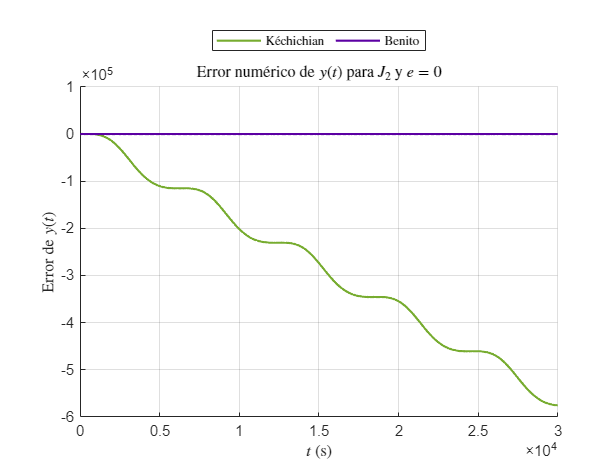

plotNumericErrors(   yJ2K',    yJ2B', dXdt(:, 2), t, 'K\''echichian', 'Benito', ...
          'Error num\''erico de $y(t)$ para $J_2$ y $e = 0$', '$t$ (s)',       'Error de $y(t)$', '#77AC30', '#5C00A3');

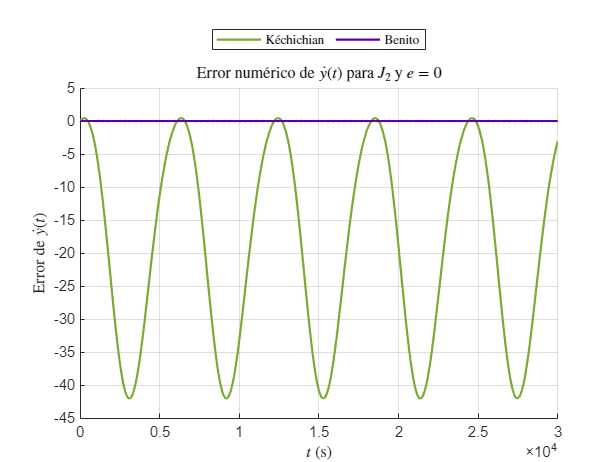

plotNumericErrors(ydotJ2K', ydotJ2B', dXdt(:, 5), t, 'K\''echichian', 'Benito', ...
    'Error num\''erico de $\dot{y}(t)$ para $J_2$ y $e = 0$', '$t$ (s)', 'Error de $\dot{y}(t)$', '#77AC30', '#5C00A3');

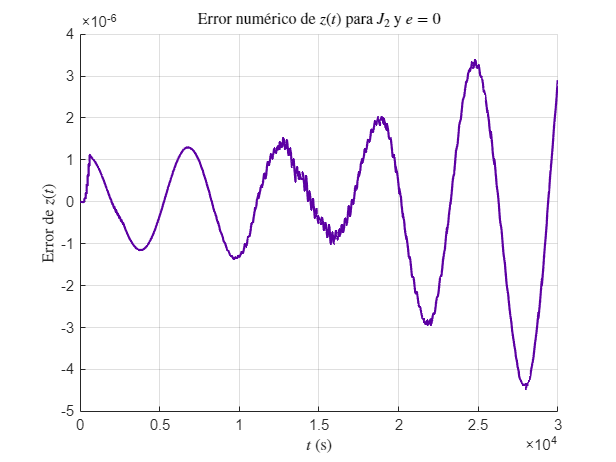

plotNumericError (   zJ2',  dXdt(:, 3), t, ...
          'Error num\''erico de $z(t)$ para $J_2$ y $e = 0$', '$t$ (s)',       'Error de $z(t)$', '#5C00A3');

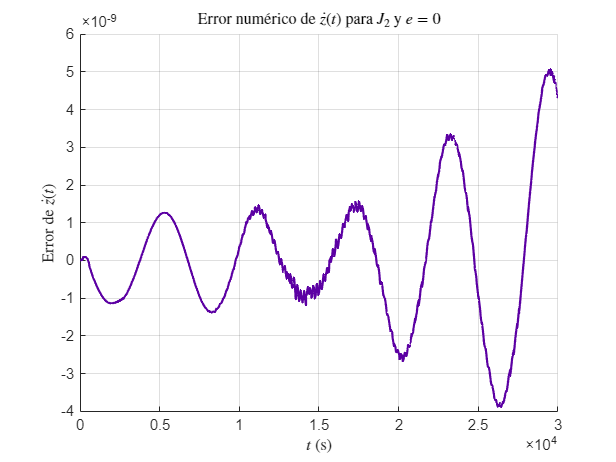

plotNumericError (zdotJ2',  dXdt(:, 6), t, ...
    'Error num\''erico de $\dot{z}(t)$ para $J_2$ y $e = 0$', '$t$ (s)', 'Error de $\dot{z}(t)$', '#5C00A3');

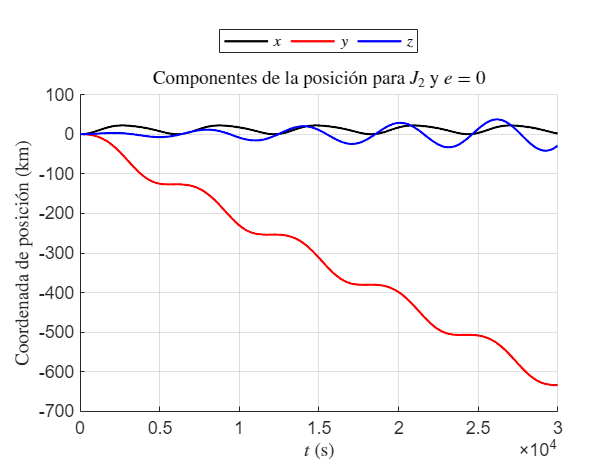




plotMultiComparisons({xJ2B / 10^3, yJ2B / 10^3, zJ2 / 10^3}, t, 'Componentes de la posici\''on para $J_2$ y $e = 0$', ...
    {'Coordenada de posici\''on (km)', '$t$ (s)'},  {'$x$', '$y$', '$z$'}, {'k', 'r', 'b'});

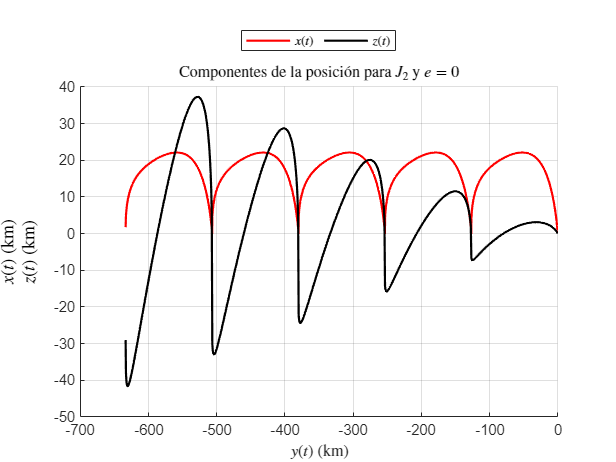

plotComparisons({yJ2B / 10^3, xJ2B / 10^3, zJ2 / 10^3}, {'$y(t)$ (km)', '$x(t)$ (km)', '$z(t)$ (km)'}, ...
   'Componentes de la posici\''on para $J_2$ y $e = 0$', {'$x(t)$', '$z(t)$'}, {'r', 'k'});

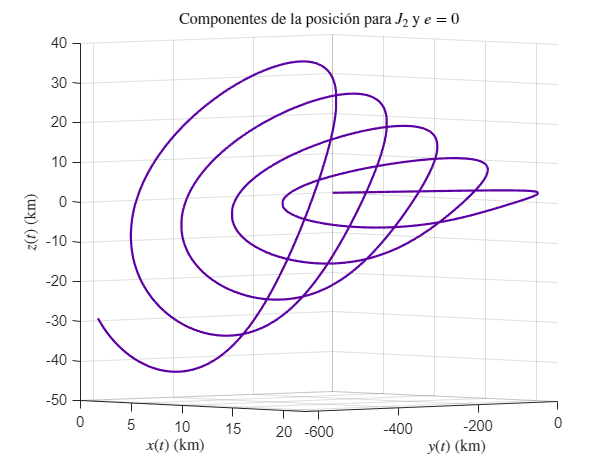

plot3D({xJ2B / 10^3, yJ2B / 10^3, zJ2 / 10^3}, [48.3 2.3], ...
    'Componentes de la posici\''on para $J_2$ y $e = 0$', ...
    {'$x(t)$ (km)', '$y(t)$ (km)', '$z(t)$ (km)'}, '#5C00A3');